# Defines pattern time for pipe status.

## This example contains: 

- Add paths and load inp file. 

- Get times. 

- Get Pipe infos. 

- Find the max length of link pipe names.

- Times. 

- Create random status for pipes every hour. 

- Unload library.

## Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


tic;

## Load inp file.

d=epanet('Net1.inp');

EPANET version {20303} loaded (EMT version {v2.3.03 - Last Update: 21/01/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


## Get times.

hydstep = d.getTimeHydraulicStep;
duration = d.getTimeSimulationDuration;

## Get Pipe infos.

pipe_count = d.getLinkPipeCount;
pipeIDs = d.getLinkPipeNameID;

## Find the max length of link pipe names.

spsmax = max(cellfun('length',pipeIDs));

## Times.

hrs = duration/3600;
hours = 0:hrs;
step = 0:hydstep/60:55; %step 30min
i=1; Time = cell(hrs,1);

for u=1:hrs
    % Create random status for pipes every hour.
    status_code = round(rand(1,pipe_count));
    status(find(status_code)) = {'Open  '};
    status(find(~status_code)) = {'Closed'};
    for j=1:length(step)
        for np=1:pipe_count
            Time{i} = sprintf('%03d:%02d:00',hours(u),30);
            sps = blanks(spsmax-length(pipeIDs{np}));
            Controls(i,: ) = ['LINK ',pipeIDs{np}, sps,' ', status{np}, ' AT CLOCKTIME ',Time{i}];
            d.addControls(['LINK ',pipeIDs{np}, sps,' ', status{np}, ' AT CLOCKTIME ',Time{i}]);
            i=i+1;
        end
    end
end

disp('Create random status')

Create random status


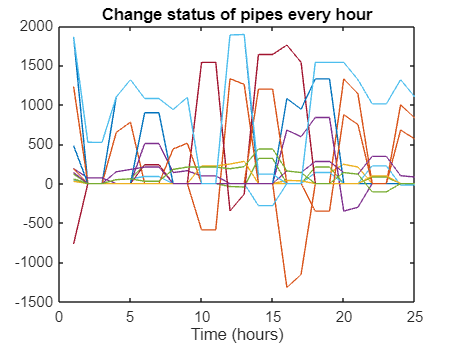

figure;
RES = d.getComputedHydraulicTimeSeries('flow');
plot(RES.Flow);
title('Change status of pipes every hour');
xlabel('Time (hours)');

## Unload library.

d.unload;

EPANET Class is unloaded


toc

Elapsed time is 1.755149 seconds.
